**Example Problem:**

A 4m x 5m x 6m room is to be heated by a baseboard resistance heater. It is desired that the resistance heater be able to raise the air temperature in the room from an initial temperature (Tin) to a final temperature (Tfinal) within a set amount of time (t). Assuming no heat losses from the room and an atmospheric pressure of 100 kPa, DETERMINE the required specific heats at room temperature.

Tin = 7+273.15; % degC to K
Tfinal = 23+273.15;% degC to K
t = 15; % min
P = 1e5; % Pa
MW = 28.97; % molecular weight of air
R = 8314; % J/kmol-K ... ideal gas constant

**Schematic:**

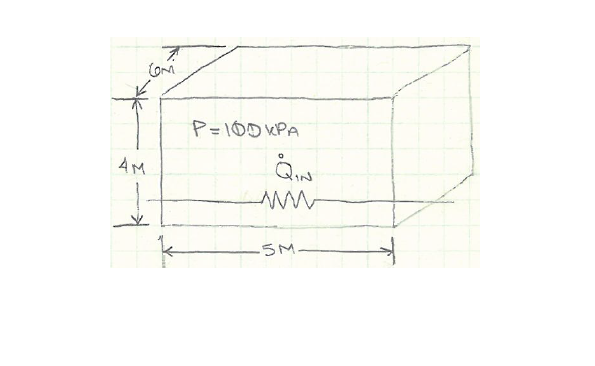

I = imread('ThermoHwExPic.bmp');
imshow(I);

V = 4*5*6; % volume of the room in m3

**Assumptions: **

- Changes in kinetic and potential energy can be neglected.

- Air behaves as an ideal gas.

- No air enters or leaves the room (i.e. mass is constant).

- Heat loss from the room is negligible (Qout = 0)

- The specific heats of air are constant and can be evaluated at 300degC.

**Analysis:**

First we'll start out with the 1st Law for a closed system:


$$Q - W = \Delta U

$$


Next we recognize that since this is a constant volume system (dV = 0), we can substitute in teh following definition for work:


$$W = \int\limits_{1}^{2 } P \ dV = 0$$


Therefore...


$$Q = \Delta U$$


**Properties:**

Cv = 718; % J/kg-K ... Cv for air at 300C

We can now sub in the definition for Cv:


$$c_V = \left( \frac{du}{dT} \right)_V$$


Rearranging for a constant volume system:


$$c_V dT = du$$


Expanding the integral and simplifying...


$$du = \int\limits_{1}^{2} c_V \ dT \ = c_V\left(T_2 - T_1 \right) = \Delta u$$


But this u is per unit mass, so for the extensive internal energy:


$$\Delta U = m*\Delta u = \rho*V*\Delta u$$


Where $\rho
$ is the density. We can also sub in the ideal gas law for $\rho *V
$ and realizing that since the mass is constant we can find it at condition 1:


$$\Delta U = \left(\frac{P*MW_{air}}{\overline{R}*T_1\right)*V*c_V*(T_2-T_1)=Q$$


Lastly, there is only heat input and no heat leaves the system:


$$Q = Q_{IN} - Q_{OUT} = Q_{IN}$$


Qin = (P*MW/(R*Tin))*V*Cv*(Tfinal-Tin); % Qin in J
Qin_dot = Qin / t / 60 / 1000 % Qin_dot in kW

Qin_dot = 1.9052

fprintf('The answer is Qin_dot = %0.2f kW', Qin_dot)

The answer is Qin_dot = 1.91 kW

 ....Now if we were to plot the power vs. time requirement:

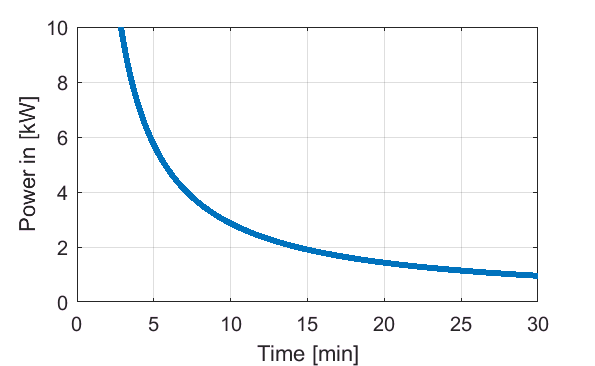

tsweep = [1:0.1:30];
Qin = (P*MW/(R*Tin))*V*Cv*(Tfinal-Tin)./tsweep./60./1000;
plot(tsweep,Qin,'LineWidth',3); 
xlabel('Time [min]');
ylabel('Power in [kW]'); 
ylim([0,10]);
grid on